% This MATLAB script identifies condensates following image preprocessing by ImageJ and cell identification by MicrobeJ.
% This script averages nine central pixels within each cell image to determine an approximate average pixel intensity for 
% non-condensate areas of the cell. For each cell, all pixels 20% higher in intensity than its approximate average 
% intensity were identified as condensates.

%% Inputs
% .mat files from MicrobeJ

%% Outputs
% MJ01_MicrobeJ_area                    Area of interpolated rod-shape cell contour
% MJ02_MicrobeJ_meanwidth               Mean width of smoothed contour
% MJ03_MicrobeJ_length                  Length of interpolated rod-shape cell contour

% O01_experiment_names                  Experiment names
% O02_num_cells                         Total # cells analyzed in experiment k
% O03_percent_condensates               Fraction of the cell population with condensates (at threshold values 1.05+0.05j)
% O04_size_cell_array                   Area of 2D interpolated cell array with corner padding (sq pixels)
% O05_size_condensates                  Area of condensates (pixels)
% O06_frac_condensate                   Area fraction of condensate (using MJ01)
% O07_condensate_norm_intensity         Average condensate intensity divided by cytoplasm intensity
% O08_num_cells_w_condensates           Number of cells with condensates
% O09_num_cells_wo_condensates          Number of cells without condensates
% O10_num_total_cells                   Number of total cells remaining with bad data removed from O2
% O11_num_condensates_cornertouching    Number of condensates per cell (8-connectivity)

%% Clear All
clear all
clc

%% Get All .mat Files in Current Directory and Save the Names
fds = fileDatastore('*.MAT', 'ReadFcn', @importdata);
fullFileNames = fds.Files;

%% Initialize Variables

i = 0; % Index for cells
j = 0; % Index for threshold
k = 0; % Index for files

cells = {};
condensates = {};

numFiles = length(fullFileNames);
O01_experiment_names = string(fullFileNames);
O02_num_cells = zeros(1,numFiles);
O03_percent_condensates = zeros(1,numFiles);

%% Store Cell Images
% For each experiment, get all of the cells in each and store them as an array of doubles. Also trim the file path off 
% of the names for data exporting.

% Experiments Loop
for k = 1 : numFiles;
    CellProperties{k} = table;
    O01_experiment_names(k) = char(erase(fullFileNames(k),"/Users/janeliao/Obermeyer Group Dropbox/Jane Liao/Jane Liao/Project - A and C Tags/EVOS Microscopy/5. Matlab Files (.mat)/Current/"));
    temp_cells = load(O01_experiment_names(k));
    O02_num_cells(k) = length(temp_cells.Experiment.Bacteria);

    % Cell Loop
    for i = 1 : O02_num_cells(k);
        try
            temp_pixels = temp_cells.Experiment.Bacteria(i).PROFILE_MEDIAL;
        catch
            temp_pixels = temp_cells.Experiment.Bacteria(i).PROFILE_MED;
        end
        CellProperties{k}.CellID(i) = i;
        CellProperties{k}.CellArea(i) = temp_cells.Experiment.Bacteria(i).SHAPE.area;
        CellProperties{k}.CellWidth(i) = temp_cells.Experiment.Bacteria(i).SHAPE.width.mean;
        CellProperties{k}.CellLength(i) = temp_cells.Experiment.Bacteria(i).SHAPE.length;
        CellProperties{k}.CellMeanIntensity(i) = temp_cells.Experiment.Bacteria(i).INTENSITY.ch.mean;
        CellProperties{k}.CellMinIntensity(i) = temp_cells.Experiment.Bacteria(i).INTENSITY.ch.min;
        
        temp_pixels.ch.pixel(temp_pixels.ch.pixel < CellProperties{k}.CellMinIntensity(i)) = 0;
        cells{k,i} = temp_pixels.ch.pixel;
        CellProperties{k}.CellImage(i) = {temp_pixels.ch.pixel};
    end
end

temp_pixels = [];

%% Classify Condensates
% Classify regions with an intensity ≥ 1.2x the cytoplasm and a size ≥ 5 contiguous pixels as a condensate and store
% in an array of doubles.

for k = 1 : numFiles;
    num_non_zero = 0;
    cytoplasm = zeros(1,9);
    avg_cytoplasm = [];
    CondensateProperties{k} = table;

    for j = 3; % Threshold of 1.2

        for i = 1:O02_num_cells(k);
            temp_cytoplasmarea = nnz(cells{k,i});
            temp_pixels = cells{k,i}; % Initialize temporary variables for pixels
            
            % Sample along the medial (x-axis) of the cell in thirds. Determine the average pixel intensity in each area.
            % The cytoplasm intensity is defined as the lowest average pixel intensity of these 3 areas.

            y_center = round(size(temp_pixels,2)/2);

            % Half Along Medial
            x_center = round(size(temp_pixels,1)/2);
            cytoplasm(1) = temp_pixels(x_center,y_center);
            cytoplasm(2) = temp_pixels(x_center+1,y_center);
            cytoplasm(3) = temp_pixels(x_center,y_center+1);
            cytoplasm(4) = temp_pixels(x_center+1,y_center+1);
            cytoplasm(5) = temp_pixels(x_center-1,y_center-1);
            cytoplasm(6) = temp_pixels(x_center-1,y_center);
            cytoplasm(7) = temp_pixels(x_center,y_center-1);
            cytoplasm(8) = temp_pixels(x_center-1,y_center+1);
            cytoplasm(9) = temp_pixels(x_center+1,y_center-1);
            avg_cytoplasm(1) = mean(cytoplasm);

            % 1/3 Along Medial
            x_center = round(size(temp_pixels,1)/3);
            cytoplasm(1) = temp_pixels(x_center,y_center);
            cytoplasm(2) = temp_pixels(x_center+1,y_center);
            cytoplasm(3) = temp_pixels(x_center,y_center+1);
            cytoplasm(4) = temp_pixels(x_center+1,y_center+1);
            cytoplasm(5) = temp_pixels(x_center-1,y_center-1);
            cytoplasm(6) = temp_pixels(x_center-1,y_center);
            cytoplasm(7) = temp_pixels(x_center,y_center-1);
            cytoplasm(8) = temp_pixels(x_center-1,y_center+1);
            cytoplasm(9) = temp_pixels(x_center+1,y_center-1);
            avg_cytoplasm(2) = mean(cytoplasm);

            % 2/3 Along Medial
            x_center = round(size(temp_pixels,1)/3*2);
            cytoplasm(1) = temp_pixels(x_center,y_center);
            cytoplasm(2) = temp_pixels(x_center+1,y_center);
            cytoplasm(3) = temp_pixels(x_center,y_center+1);
            cytoplasm(4) = temp_pixels(x_center+1,y_center+1);
            cytoplasm(5) = temp_pixels(x_center-1,y_center-1);
            cytoplasm(6) = temp_pixels(x_center-1,y_center);
            cytoplasm(7) = temp_pixels(x_center,y_center-1);
            cytoplasm(8) = temp_pixels(x_center-1,y_center+1);
            cytoplasm(9) = temp_pixels(x_center+1,y_center-1);
            avg_cytoplasm(3) = mean(cytoplasm);
            
            % Final Intensity Threshold: 1.2x Intensity of Cytoplasm
            final_threshold = min(avg_cytoplasm) * (1.05+0.05*(j));

            % Determine and Save Condensate Images 
            % Set all pixels below the intensity threshold to zero
            temp_pixels(temp_pixels < final_threshold) = 0;
            
            % Set all pixels < 5 contiguous pixels to zero.
            if nnz(temp_pixels) ~= 0
                mask = bwareaopen(im2bw(temp_pixels),5); % Returns array with 0 if below size filter and 1 if above
                temp_pixels = temp_pixels .* mask;
                mask = [];
            end

            % Analyze Condensate Images for Outputs
            temp_pixels_bw = bwconncomp(temp_pixels);
            temp_properties = regionprops('table',temp_pixels_bw,temp_pixels,"Area","MaxIntensity","MeanIntensity","SubarrayIdx");
            temp_properties.CellID(:) = i;
            temp_properties.CellArea(:) = CellProperties{k}.CellArea(i);
            temp_properties.CytoplasmArea(:) = temp_cytoplasmarea - nnz(temp_pixels);
            temp_properties.CytoplasmMeanIntensity(:) = sum(cells{k,i} - temp_pixels,'all') / nnz(cells{k,i} - temp_pixels);
            [CondensateProperties{k}] = [CondensateProperties{k}; temp_properties];

            % If current cell has a condensate, increase the count of condensate-forming cells.
            if nnz(temp_pixels) ~= 0
                num_non_zero = num_non_zero+1;
                CellProperties{k}.CondensateImage(i) = {temp_pixels};
                CellProperties{k}.TotalCondensateArea(i) = nnz(temp_pixels);
                CellProperties{k}.NumberofCondensates(i) = temp_pixels_bw.NumObjects;
                CellProperties{k}.CytoplasmMeanIntensity(i) = sum(cells{k,i} - temp_pixels,'all') / nnz(cells{k,i} - temp_pixels);
            else
                CellProperties{k}.NumberofCondensates(i) = 0;
            end

        end

        % Determine the percentage of cells with condensates
        O08_num_cells_w_condensates(k) = num_non_zero;
        O03_percent_condensates(j,k) = num_non_zero / O02_num_cells(k);
        num_non_zero = 0;

       % Re-initialize vaiables
       temp_pixels = [];   
    end
CondensateProperties{k}.IntensityRatio = CondensateProperties{k}.MeanIntensity ./ CondensateProperties{k}.CytoplasmMeanIntensity;
CondensateProperties{k}.AreaFraction = CondensateProperties{k}.Area ./ CondensateProperties{k}.CellArea;
end

%% Combine Replicates into One File
k = 1;
CellProperties_AllReps = table;
CondensateProperties_AllReps = table;

for k = 1:numFiles;
    CellProperties_AllReps = [CellProperties_AllReps; CellProperties{k}];
    CondensateProperties_AllReps = [CondensateProperties_AllReps; CondensateProperties{k}];
end

%% Cell Population Properties
CellPopulationProperties = table;
CellPopulationProperties.ExperimentNames = O01_experiment_names;
CellPopulationProperties.TotalNumberofCells = O02_num_cells';
CellPopulationProperties.CondensateFormingCells = O08_num_cells_w_condensates';
CellPopulationProperties.NonCondensateFormingCells = CellPopulationProperties.TotalNumberofCells - CellPopulationProperties.CondensateFormingCells;
CellPopulationProperties.FractionofCellswithCondensates = O03_percent_condensates(j,:)';

for k = 1:size(CellProperties,2)
    CellPopulationProperties.MedianCellArea(k) = median(CellProperties{1,k}.CellArea);
    CellPopulationProperties.MedianMeanCellWidth(k) = median(CellProperties{1,k}.CellWidth);
    CellPopulationProperties.MedianCellLength(k) = median(CellProperties{1,k}.CellLength);
end

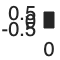

%% Condensate Localization Probability Density Histogram
k = 1;
MaximaLongPosition = [];
MaximaShortPosition = [];
short = [];
long = [];
backgroundrow = [];
backgroundcolumn = [];

for k = 1:numFiles
    l = 1;
    for l = 1 : size(CondensateProperties{1,k},1)
            row = cell2mat(CondensateProperties{1,k}.SubarrayIdx(l,1));
            column = cell2mat(CondensateProperties{1,k}.SubarrayIdx(l,2));
            temp_pixels = CellProperties{1,k}.CondensateImage{CondensateProperties{1, k}.CellID(l)};
            [MaximaLongPosition MaximaShortPosition] = find(temp_pixels(row,column) == CondensateProperties{1,k}.MaxIntensity(l));
            MaximaLongPosition = row(MaximaLongPosition);
            MaximaShortPosition = column(MaximaShortPosition);

            %If more than 1 pixel a condensate has the same max intensity,
            %average the locations of the pixels
            if size(MaximaLongPosition,2) > 1
                MaximaLongPosition = mean(MaximaLongPosition);
                MaximaShortPosition = mean(MaximaShortPosition);
            end
            
            %Store the long-short coordinates of maxima within condensates
            CondensateProperties{1,k}.MaximaLongPosition(l) = MaximaLongPosition;
            CondensateProperties{1,k}.MaximaShortPosition(l) = MaximaShortPosition;
            
            %Normalize long-short coordinates to 2x1 um cell
            MaximaLongPosition = (MaximaLongPosition / size(temp_pixels,1) * 2) - 1;
            MaximaShortPosition = (MaximaShortPosition / size(temp_pixels,2)) - 0.5;
            
            %If a cell has 1 condensate, reflect it into the positive long half
            %to align
            if CellProperties{1,k}.NumberofCondensates(CondensateProperties{1,k}.CellID(l)) == 1
                MaximaLongPosition = abs(MaximaLongPosition);
            end
            
            long = [long, MaximaLongPosition];
            short = [short, MaximaShortPosition];
    end
end

CondensateLocalizationDensity = histogram2(long,short,'YBinLimits',[-0.5 0.5],'XBinLimits',[-1 1],'NumBins',[20 10],'DisplayStyle','tile','ShowEmptyBins','on');

CondensateLocalizationDensity = CondensateLocalizationDensity.Values;
sum(CondensateLocalizationDensity,'all') == sum(CellProperties_AllReps.NumberofCondensates,'all')

ans = logical
   1


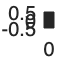

CondensateLocalizationDensity = CondensateLocalizationDensity ./ sum(CondensateLocalizationDensity,'all');

for k = 1:numFiles
    for i = 1:CellPopulationProperties.TotalNumberofCells(k)
        if CellProperties{1,k}.NumberofCondensates(i) ~= 0
            [temp_backgroundlong temp_backgroundshort] = find(cells{k,i}==0);
            temp_backgroundlong = temp_backgroundlong ./ size(cells{k,i},1) * 2 - 1;
            temp_backgroundshort = temp_backgroundshort ./ size(cells{k,i},2) - 0.5;
            backgroundrow = [backgroundrow; temp_backgroundlong];
            backgroundcolumn = [backgroundcolumn; temp_backgroundshort];
        end
    end
end

BackgroundLocalizationDensity = histogram2(backgroundrow,backgroundcolumn,'YBinLimits',[-0.5 0.5],'XBinLimits',[-1 1],'NumBins',[20 10],'DisplayStyle','tile','ShowEmptyBins','on');
BackgroundLocalizationDensity = BackgroundLocalizationDensity.Values;

tiledlayout(1,2)

nexttile
X = -0.45:0.1:0.45;
Y = -0.95:0.1:0.95;
imagesc('XData',X,'YData',Y,'Cdata',CondensateLocalizationDensity)
colorbar
colormap viridis
clim([0 0.12])
daspect([1 1 1])
set(gca,'xtick', -0.5:0.1:0.5, 'ytick', -1:0.1:1);
set(gca,'xgrid', 'on', 'ygrid', 'on', 'gridlinestyle', '-', 'xcolor', 'k', 'ycolor', 'k');

nexttile
contourf(X,Y,BackgroundLocalizationDensity,[0.1*sum(CellProperties_AllReps.NumberofCondensates,'all') 0.1*sum(CellProperties_AllReps.NumberofCondensates,'all')])
ylim([-1,1]); 
xlim([-0.5,0.5]); 
colorbar
daspect([1 1 1])
set(gcf,'Position',[400 400 600 300])

FileName = input('Enter Protein and Time: ','s')

FileName = 'sfGFP_2h'

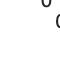

print('-vector', '-depsc',FileName)

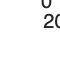

%% Intensity Distributions
CondensateFormingCells_AllReps = CellProperties_AllReps(CellProperties_AllReps.NumberofCondensates~=0,:);
CondensateFormingCells_AllReps.TotalCondensateAreaFraction = CondensateFormingCells_AllReps.TotalCondensateArea ./ CondensateFormingCells_AllReps.CellArea;
histogram(CondensateFormingCells_AllReps.CellMeanIntensity,'BinWidth',20)
hold on
histogram(CondensateFormingCells_AllReps.CytoplasmMeanIntensity,'BinWidth',20)
hold on
histogram(CondensateProperties_AllReps.MeanIntensity,'BinWidth',20)

%% Clear Temporary Variables and Save Data Tables as .mat File
FileName = strcat(FileName,'.mat')

FileName = 'sfGFP_2h.mat'

save(FileName, 'CellPopulationProperties', 'CellProperties_AllReps', 'CondensateFormingCells_AllReps', 'CondensateProperties_AllReps', 'CellProperties', 'CondensateProperties')
close all
clearvars -except CellProperties_AllReps CondensateFormingCells_AllReps CondensateProperties_AllReps CellProperties CondensateProperties CellPopulationProperties